# Test1

## 실험 가정

탑재체의 출발부분부터 신호를 보낸다고 가정.

clear all;
dt = 1;
dD = 1;
t = 0 : dt : 10;       % 총 걸린시간 [s]
D = 0 : dD : 10;       % 총 이동거리 [m]
v = 1;                 % 탑재체 속도 [m/s]
h = 20000;   % 20[km]  % 탑재체 고도 [m]

## +z축에서 바라본 탑재체 동선 및 송수신 신호간격

총 이동거리 10m, 총 걸린시간 10s => 송수신 신호 간격(PulseWidth = 1s)

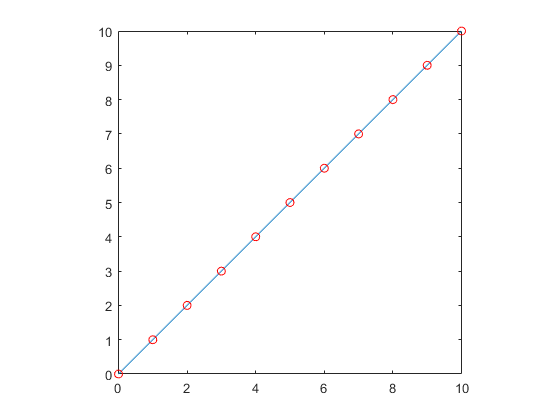

x = 0 : 0.01 : 10;
y = 0 : 0.01 : 10;
plot(x,y)
axis('square');

hold on;
for i = 1:11      
    x_trans = 0 : 1 : length(D)-1;
    y_trans = 0 : 1 : length(D)-1;
    pause(0.5);
    drawnow;
    plot(x_trans(i),y_trans(i),"Marker",'o',"Color",'r')
end
hold off;

## x,y평면을 측면에서 바라본 모습 (지표의 단면)

측면에서 지표를 바라볼 때, 신호가 반사되어서 지표에 반사되는 부분을 나타냄 

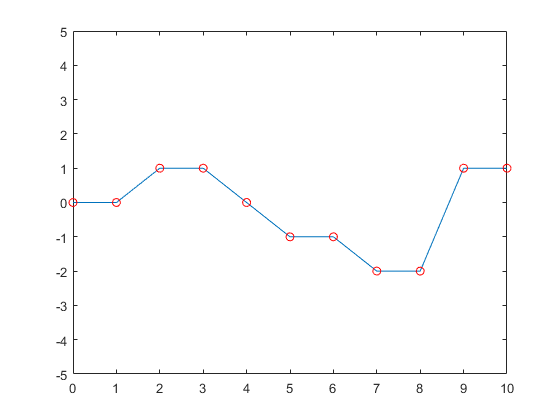

% ex) input = [0, 1, 0, -1] -> 탑재체에서의 거리차
% [0, 1, 0, -1] = 20km, 19.999km, 20km, 20.001km

ground = [0, 0, 1, 1, 0, -1, -1, -2, -2, 1, 1]; 
plot(t,ground)
axis([0,10,-5,5]);

hold on;
for i = 1:11
    input_trans = 0 : 1 : length(ground)-1;
    pause(0.5);
    drawnow;
    plot(t(i),ground(i),"Marker",'o',"Color",'r')
end
hold off;

## 신호정의 및 거리계산

거리 = 시간 x 속력,    signal 속도 = 3 x 10^8 [m/s], plusewidth = 10 [us] 

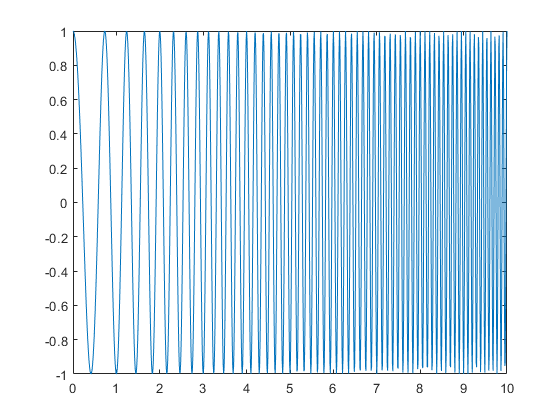

% chirp = A cos[2*pi*fo*(t-tau)+(mu/2)*(t-tau)^2] -> 송신 signal
dtt = 0.01;
tt = 0 : dtt : 10;      % 10 [us]
c = 3*10^8;             % signal 속도 [m]
chirp1_gain = 1;
chirp1_fo = 1;
chirp1_mu = 1;
chirp1_delta_tau = 0;

signal = chirp1_gain.*cos(2*pi.*(chirp1_fo*(tt - chirp1_delta_tau) + (chirp1_mu/2).*(tt - chirp1_delta_tau).^2));
plot(tt,signal)

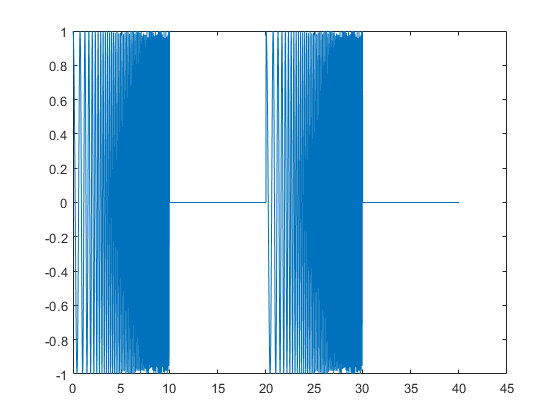


% total signal
rt1 = [signal, zeros(1,length(tt))];
rt2 = [signal, zeros(1,length(tt))];
total_signal = [rt1 , rt2];
plot((0:length(total_signal)-1)*dtt,total_signal)

% 예시로 2개의 sample만 실험...
% 총 11개의 samples... PRF는? 신호가 겹쳐졌을 때 분해능을 봐야하는 것 아닌가??

% 거리계산
R = (h-ground);
delta_t = R/(c*10^-3);
delta_t

delta_t =     0.0667    0.0667    0.0667    0.0667    0.0667    0.0667    0.0667    0.0667    0.0667    0.0667    0.0667


% ...??? 시간을 가지고 거리를 구해야하는데 정반대로... 시간을 구한다..?
